# Trasformata impulso e creazione di rumore casuale dallo spettro corrispondente

In questo esempio vengono mostrate le seguenit operazioni:

- costruzione di un segnale impulsivo digitale (ovvero con valore diverso da zero ma finito per un solo campione)

- calcolo FFT

- le fasi vengono 'mescolate' casualmente mediante il comando 'rand'

- si antitrasforma andando a creare un segnale apparemntemente totalmente diverso da quello impulsivo: un rumore completamente casuale

close all
clear all
clc

#### 1. Si costruisce l'impulso:

Tc = 0.1;
Tend = 10;
t = 0:Tc:Tend;
ss = length(t);
s = zeros(size(t));
s(1) = 1;


#### 2. Si calcola la FFT e si mostrano segnale e trasformata in Modulo e Fase

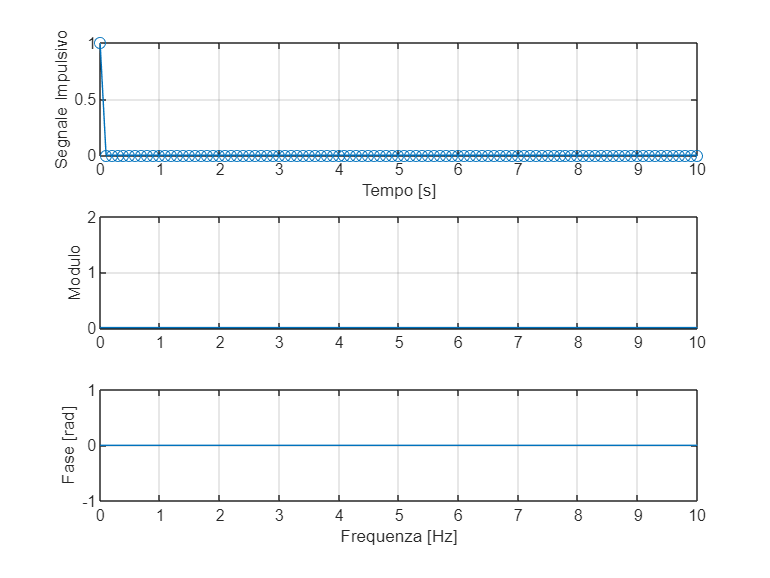

s_FFT = fft(s)/ss;
ff = 0:1/Tend:1/Tc;
subplot(3,1,1), plot(t , s , '-o'), ylabel('Segnale Impulsivo'), grid on
xlabel('Tempo [s]')
subplot(3,1,2), plot(ff , abs(s_FFT)), ylabel('Modulo'), axis([0 10 0 2]), grid on
subplot(3,1,3), plot(ff , angle(s_FFT)), ylabel('Fase [rad]'), xlabel('Frequenza [Hz]'), grid on

Notiamo che la fase è sempre nulla. Quali sono dunque le componenti del segnale impulsivo?

media = s_FFT(1);               % valore medio
nmax = 15                       % numero di componenti da mostrare

nmax = 15

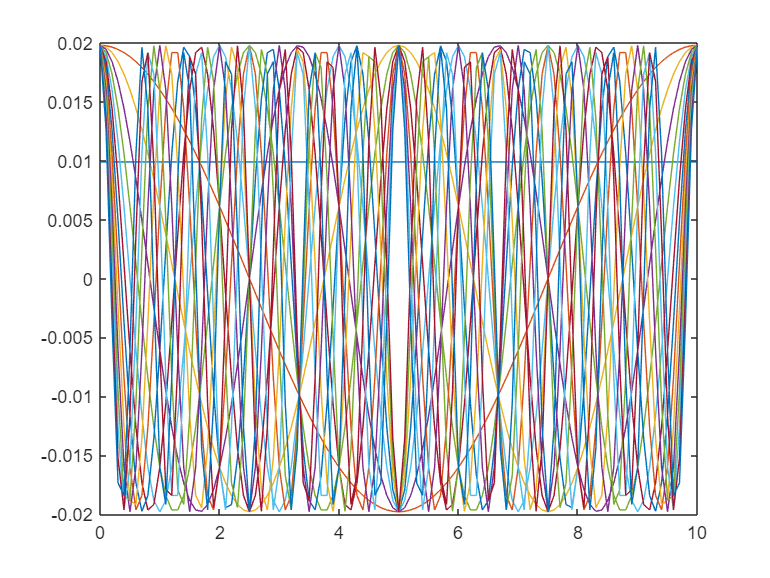

figure
plot(t, ones(size(s))*media)     % segnale corrispondente alla componente valore medio
hold on
for i = 2:nmax
    plot(t,2 * abs(s_FFT(i)) * cos(2 * pi * ff(i) * t + angle(s_FFT(i)) ))
    % sf = 2 * abs(s_FFT(i)) * cos(2 * pi * ff(i) * t + angle(s_FFT(i)) );
end

DOMANDA: Notate qualcosa?

#### 3. Ricaviamo un segnale completamente casuale mescolando le fasi:

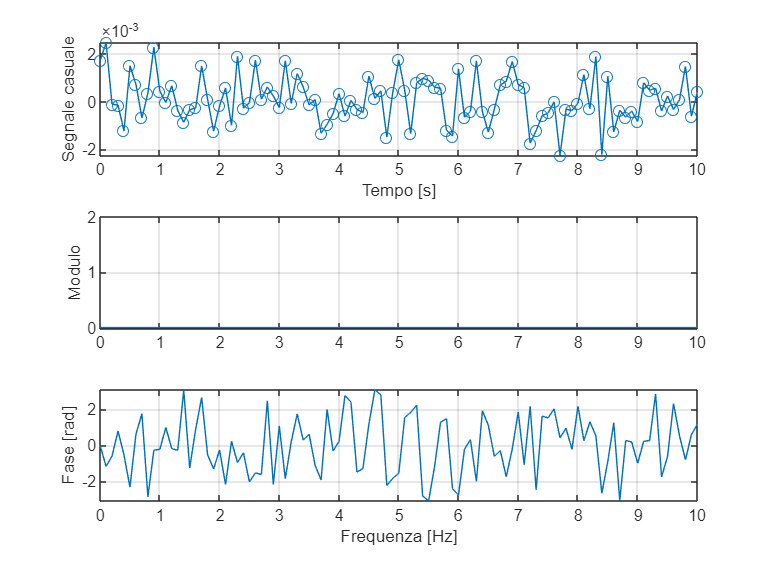

phirand = 2*pi*rand(1, floor(length(t)/2));
s_FFT = s_FFT.*[1 exp(1i*phirand) fliplr(exp(-1i*phirand))];

yrand = ifft(s_FFT);
figure, 
subplot(3,1,1), plot(t , yrand , '-o'), ylabel('Segnale casuale'), grid on 
xlabel('Tempo [s]')
subplot(3,1,2), plot(ff , abs(s_FFT)), ylabel('Modulo'), axis([0 10 0 2]), grid on
subplot(3,1,3), plot(ff , angle(s_FFT)), ylabel('Fase [rad]'), xlabel('Frequenza [Hz]'), grid on

Notiamo che la fase è casuale adesso. Quali sono ora le componenti del segnale impulsivo?

media = s_FFT(1);               % valore medio
nmax = 17                       % numero di componenti da mostrare

nmax = 17

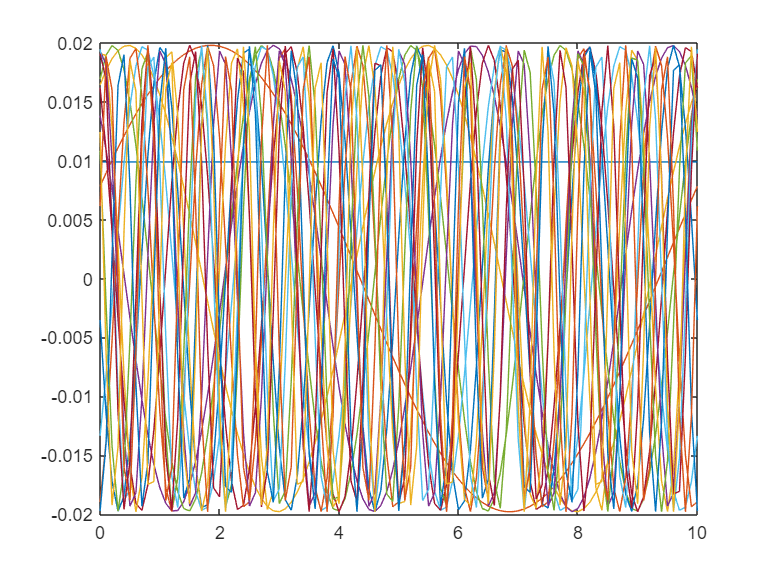

figure
plot(t,ones(size(s))*media)     % segnale corrispondente alla componente valore medio
hold on
for i = 2:nmax
    plot(t,2 * abs(s_FFT(i)) * cos(2 * pi * ff(i) * t + angle(s_FFT(i)) ))
    % sf = 2 * abs(s_FFT(i)) * cos(2 * pi * ff(i) * t + angle(s_FFT(i)) );
end

DOMANDA: Notate qualcosa di diverso ora?